%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% Compare_Gamma_FreqResponse
%
% Compare gamma computed for EQ14 chameleon data, with generic FP07 
% response correction, vs a different (lower cutoff). Could this
% explain why gamma is so small?
%
% Looking at dT/dz spectra from EQ14 profile, it seemed like the FP07 roll-off 
% occurred at lower frequencies (~7-10Hz) than the generic cutoff used (32Hz)
%
% Results: gamma is increased slightly, but not enough to make it near 0.2
%
% 10/18/16 - A.Pickering - andypicke@gmail.com
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

clear ; close all

addpath /Users/Andy/Cruises_Research/GenMatlabFunctions/


% load data w/ generic ferq response
load('/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/Data/chameleon/processed/Cstar=0_032/sum/eq14_sum_clean.mat')
cham0=cham; clear cham

% load data w/ different freq respon.
load('/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/Data/chameleon/processed_AP_7hz/sum/eq14_sum_clean.mat')
cham1=cham; clear cham

% compute gammas

gam0 = cham0.N2 .* cham0.CHI ./2 ./ cham0.EPSILON ./ (cham0.DTDZ_RHOORDER.^2);

gam1 = cham1.N2 .* cham1.CHI ./2 ./ cham1.EPSILON ./ (cham1.DTDZ_RHOORDER.^2);


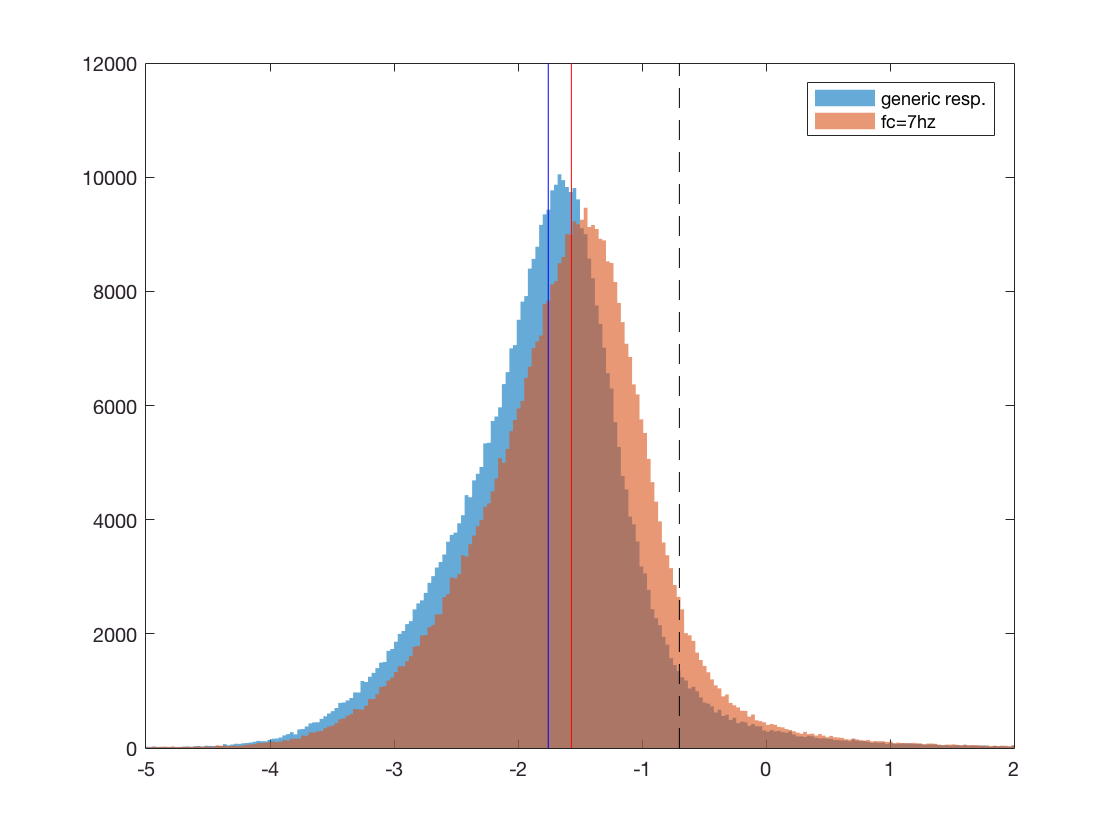

% Plot

figure(1);clf
h0=histogram(log10(gam0(:)),'edgecolor','none');
hold on
h1=histogram(log10(gam1(:)),h0.BinEdges,'edgecolor','none');
xlim([-5 2])
legend([h0 h1],'generic resp.','fc=7hz')
freqline(nanmedian(log10(gam0(:))),'b');
freqline(nanmedian(log10(gam1(:))),'r');
freqline(log10(0.2),'k--');

%%

Using a lower frequency correction cutoff increases gamma a bit, but nowhere close to 0.2

nanmedian(gam0(:))

ans = 0.0175

nanmedian(gam1(:))

ans = 0.0269